# Analisi Mobilità Manipolatore Planare RRR

L'analisi della mobilità istantanea di un manipolatore planare con tre giunti rotoidali (RRR) si basa sullo studio delle proprietà della matrice Jacobiana, $J(q)$, che lega le velocità dei giunti $\dot{q}$ alle velocità dell'end-effector $v$ tramite la relazione $v=J(q)\;\dot{q}$

Si devono determinare:

- Lo **Spazio** delle **Velocità Raggiungibili** ($R(J)$): L'insieme di tutte le velocità che l'end-effector può assumere.

- Le **Direzioni** di **Moto Precluse** ($N(J^T )$): Le direzioni in cui l'end-effector non può muoversi istantaneamente.

- Gli **Automovimenti** ($N(J)$): Le combinazioni di velocità dei giunti che non producono movimento dell'end-effector, ma solo un riarrangiamento interno del robot.

% Risoluzione percorso cartella funzioni ausiliarie Codici Matlab
if ~exist('Compute_DH_Transformations', 'file') || ~exist('Compute_Rotation_Matrix', 'file')
    candDirs = {pwd, fileparts(pwd)};
    try
        edFile = matlab.desktop.editor.getActiveFilename;
        candDirs = [candDirs, {fileparts(edFile), fileparts(fileparts(edFile))}];
    catch
    end
    for iCand = 1:numel(candDirs)
        cDir = candDirs{iCand};
        if isfolder(cDir) && (isfile(fullfile(cDir, 'Compute_DH_Transformations.m')) || isfile(fullfile(cDir, 'Compute_Rotation_Matrix.m')))
            addpath(cDir);
            break;
        end
    end
end
clc; clear; close all;
% Parametri Manipolatore
syms q1 q2 q3 l1 l2 l3 real;

Il primo passo consiste nel definire matematicamente il robot e calcolare la posizione del suo end-effector utilizzando la convenzione di Denavit-Hartenberg (DH)

% Definizione Tabelle DH Struttura
DH_Table = [q1, 0, 0, l1;
            q2, 0, 0, l2;
            q3, 0, 0, l3];
% q1 = pi/4;
% q2 = pi/2;
% q3 = pi/4;

% Calcolo Matrici Trasformazione E Rotazione Struttura
[T, R] = Compute_DH_Transformations(DH_Table);

T00 = eye(4);
T01 = simplify(T(:,:,1));       % Trasformazione da 0 a 1
T02 = simplify(T01 * T(:,:,2)); % Trasformazione da 0 a 2
T03 = simplify(T02 * T(:,:,3)); % Trasformazione da 0 a 3

Il vettore di posizione $p$ dell'end-effector può essere estratto dalla matrice $^0 T_3$ in quanto è la quarta colonna. Poiché l'analisi di mobilità si concentra sul piano $XY$ si prendono le prime due componenti del vettore posizione.

% Posizione dell'End-Effector
p_E = T03(1:3, 4);
fprintf('Vettore Posizione p RRR Planare:');

Vettore Posizione p RRR Planare:

disp(p_E);

$$\left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ 0 \end{array}\right)$$

Lo **Jacobiano analitico**, indicato come $J_r (q)$, è la matrice che lega la velocità dei giunti $\dot{q}$ alla velocità lineare dell'end-effector $v$ secondo la relazione:


$$v=J_r (q)\dot{q}$$


Dato che si conosce l'espressione simbolica del vettore posizione dell'end-effector $p$ in funzione del vettore delle coordinate dei giunti $q$, lo Jacobiano si calcola come la matrice delle derivate parziali di ogni componente della posizione rispetto a ogni coordinata di giunto.


$$J_r (q) = \frac{\partial p}{\partial q}$$


% Vettori z (Assi Di Rotazione)
z0 = T00(1:3, 3); % Asse di rotazione del giunto 1
z1 = T01(1:3, 3); % Asse di rotazione del giunto 2
z2 = T02(1:3, 3); % Asse di rotazione del giunto 3

% Vettori p (Posizioni Origini Dei Riferimenti)
p0 = T00(1:3, 4); % Origine del frame 0
p1 = T01(1:3, 4); % Origine del frame 1
p2 = T02(1:3, 4); % Origine del frame 2

% Valori Per J1
J_L1 = cross(z0, p_E - p0);
J_A1 = z0;
J1 = [J_L1; J_A1];

% Valori Per J2
J_L2 = cross(z1, p_E - p1);
J_A2 = z1;
J2 = [J_L2; J_A2];

% Valori Per J3
J_L3 = cross(z2, p_E - p2);
J_A3 = z2;
J3 = [J_L3; J_A3];

% Costruzione Jacobiano Geometrico
J_q = simplify([J1, J2, J3]);

fprintf('Jacobiano Geometrico Manipolatore RRR Planare Simbolico');

Jacobiano Geometrico Manipolatore RRR Planare Simbolico

disp(J_q);

$$\begin{array}{l} \left(\begin{array}{ccc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)-\sigma_{1} & -l_{2}\,\sin\left(q_{1}+q_{2}\right)-\sigma_{1} & -\sigma_{1}\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+\sigma_{2} & l_{2}\,\cos\left(q_{1}+q_{2}\right)+\sigma_{2} & \sigma_{2}\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

% Estrazione Jacobiano Lineare (Prime Due Righe)
J_L = J_q(1:2,1:3);
fprintf('Jacobiano Lineare Manipolatore RRR Planare Simbolico:');

Jacobiano Lineare Manipolatore RRR Planare Simbolico:

disp(J_L);

$$\begin{array}{l} \left(\begin{array}{ccc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)-\sigma_{1} & -l_{2}\,\sin\left(q_{1}+q_{2}\right)-\sigma_{1} & -\sigma_{1}\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+\sigma_{2} & l_{2}\,\cos\left(q_{1}+q_{2}\right)+\sigma_{2} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

Una configurazione $q$ è **singolare** quando lo Jacobiano $J_r (q)$ perde di rango, ovvero $\rho \bigl(J_r (q)\bigr)<m$. Per una matrice non quadrata come in questo caso ($m\times n=2\times 3$).

Un metodo robusto per trovare queste condizioni è analizzare la matrice di Gram $J_r (q)\cdot {\bigl((J_r (q)\bigr)}^T$ che è sempre quadrata ($m\times m$) e perde di rango esattamente quando $J_r (q)$ perde di rango. La condizione di singolarità si traduce quindi nel trovare le configurazioni $q$ per cui il determinante di questa matrice è nullo.

% Calcolo Condizione Singolarità: det(J(q) * J(q)^T) = 0
G = J_L * J_L.';
det_G = simplify(det(G));

disp('Determinante Matrice Di Gram (det(J_r * J_r^T)):');

Determinante Matrice Di Gram (det(J_r * J_r^T)):


disp(det_G);

$$\frac{{l_{1}}^{2}\,{l_{2}}^{2}}{2}+{l_{1}}^{2}\,{l_{3}}^{2}+{l_{2}}^{2}\,{l_{3}}^{2}-\frac{{l_{1}}^{2}\,{l_{2}}^{2}\,\cos\left(2\,q_{2}\right)}{2}-{l_{2}}^{2}\,{l_{3}}^{2}\,\cos\left(2\,q_{3}\right)-{l_{1}}^{2}\,{l_{3}}^{2}\,\cos\left(2\,q_{2}+2\,q_{3}\right)-l_{1}\,l_{2}\,{l_{3}}^{2}\,\cos\left(q_{2}+2\,q_{3}\right)-{l_{1}}^{2}\,l_{2}\,l_{3}\,\cos\left(2\,q_{2}+q_{3}\right)+l_{1}\,l_{2}\,{l_{3}}^{2}\,\cos\left(q_{2}\right)+{l_{1}}^{2}\,l_{2}\,l_{3}\,\cos\left(q_{3}\right)$$

assume(l1 > 0 & l2 > 0 & l3 > 0);
assume([q2, q3], 'real');

disp('Condizione Di Singolarità:');

Condizione Di Singolarità:


disp(det_G == 0);

$$\frac{{l_{1}}^{2}\,{l_{2}}^{2}}{2}+{l_{1}}^{2}\,{l_{3}}^{2}+{l_{2}}^{2}\,{l_{3}}^{2}-\frac{{l_{1}}^{2}\,{l_{2}}^{2}\,\cos\left(2\,q_{2}\right)}{2}-{l_{2}}^{2}\,{l_{3}}^{2}\,\cos\left(2\,q_{3}\right)-{l_{1}}^{2}\,{l_{3}}^{2}\,\cos\left(2\,q_{2}+2\,q_{3}\right)-l_{1}\,l_{2}\,{l_{3}}^{2}\,\cos\left(q_{2}+2\,q_{3}\right)-{l_{1}}^{2}\,l_{2}\,l_{3}\,\cos\left(2\,q_{2}+q_{3}\right)+l_{1}\,l_{2}\,{l_{3}}^{2}\,\cos\left(q_{2}\right)+{l_{1}}^{2}\,l_{2}\,l_{3}\,\cos\left(q_{3}\right)=0$$

La *condizione di singolarità* è complessa e difficile da interpretare direttamente. Spesso, le condizioni di singolarità dipendono dagli angoli relativi tra i bracci, non dalla loro orientazione globale. Per semplificare l'espressione, si considera il caso specifico in cui i bracci hanno lunghezza unitaria ($l_1 =l_2 =l_3 =1$) in modo da mantenere tutte le proprietà cinematiche rilevanti.

% Sostituzione Parametri Lunghezza
det_G_Sub = subs(det_G, [l1, l2, l3], [1, 1, 1]);

% Semplificazione
det_G_Sub = simplify(det_G_Sub);

disp('Condizione Di Singolarità Semplificata Con l1=l2=l3=1:');

Condizione Di Singolarità Semplificata Con l1=l2=l3=1:


disp(det_G_Sub == 0);

$$\cos\left(q_{2}\right)-\cos\left(2\,q_{2}+q_{3}\right)-\frac{\cos\left(2\,q_{2}\right)}{2}-\cos\left(2\,q_{3}\right)-\cos\left(2\,q_{2}+2\,q_{3}\right)-\cos\left(q_{2}+2\,q_{3}\right)+\cos\left(q_{3}\right)+\frac{5}{2}=0$$

La condizione di singolarità semplificata ottenuta per lunghezze unitarie rivela che le singolarità dipendono solo dagli angoli $q_2$ e $q_3$. Questo è coerente con la natura planare del manipolatore, dove la posa della base non altera la raggiungibilità dello spazio di lavoro ma solo la sua orientazione. Le condizioni esatte in cui il determinante si annulla corrispondono a configurazioni geometricamente significative:

- Quando i bracci sono completamente estesi o ripiegati, l'end-effector si trova sul confine dello spazio di lavoro e perde un grado di libertà (*Singolarità Di Bordo*). Questo accade quando $q_2$ o $q_3$ sono $0$ oppure $\pi$.

- Quando l'end-effector si ripiega su un giunto precedente, cioè la punta del robot si trova alla base del giunto $q_1$. Questa singolarità dipende dalle lunghezze dei bracci e dagli angoli $q_2$ e $q_3$.

Quindi, poichè la matrice Jacobiana $J$ non è costante, ma dipende dalla configurazione attuale del robot, descritta dal vettore delle variabili di giunto, il determinante e tutte le proprietà (rango, immagine e nucleo) sono **locali**, ovvero variano con $q$:


$$det(J)=det(J(q)) \qquad \rho (J)=\rho J(q) \qquad R(J)=R(J(q)) \qquad N(J)=N(J(q))$$


## Configurazione 1: Robot Ripiegato

I parametri del robot sono


$$l_1 =l_2 =l_3 =1$$



$$q_1 =0~~~~q_2 =\frac{\pi }{2}~~~~q_3 =-\frac{\pi }{2}$$


% Valori numerici per la configurazione
l_vals = [1, 1, 1];
q1_val = 0;
q2_val = pi/2;
q3_val = -pi/2;
q_vals = [q1_val, q2_val, q3_val];

fprintf('------------ Configurazione q = [%.2f, %.2f, %.2f] ------------', q_vals(1), q_vals(2), q_vals(3));

------------ Configurazione q = [0.00, 1.57, -1.57] ------------

% Sostituzione dei valori numerici nello Jacobiano lineare simbolico
vars_sym = [l1, l2, l3, q1, q2, q3];
vals_num = [l_vals, q_vals];
J1_num = double(subs(J_L, vars_sym, vals_num));

fprintf('Jacobiano Lineare Numerico:\n');

Jacobiano Lineare Numerico:


disp(J1_num);

    -1    -1     0
     2     1     1



% Verifica Singolarità
rank_J1 = rank(J1_num);
fprintf('Rango dello Jacobiano: %d\n', rank_J1);

Rango dello Jacobiano: 2


% Dimensione Spazio Lavoro
m = size(J_L, 1);
% Numero Di Giunti
n = size(DH_Table, 1);

if rank_J1 < m
    fprintf('Configurazione Singolare (Rango < m)');

    % Spazio Velocità Raggiungibili (Immagine di J)
    R_J1 = orth(J1_num);
    fprintf('Base Spazio Velocità Raggiungibili R(J):\n');
    disp(R_J1);
    % L'End-Effector Può Muoversi Solo Lungo La Direzione Di Questo Vettore

    % Direzioni Di Moto Precluse (Nucleo di J^T)
    N_J1_T = null(J1_num.');
    fprintf('Base Direzioni Di Moto Precluse N(J^T):\n');
    disp(N_J1_T);
    % L'End-Effector È Bloccato E Non Può Muoversi Lungo Direzione Di Questo Vettore
else
    fprintf('Configurazione NON Singolare (Rango Pieno)');

    % Spazio Velocità Raggiungibili (Immagine di J)
    R_J1 = orth(J1_num);
    fprintf('Base Spazio Velocità Raggiungibili R(J):\n');
    disp(R_J1);
    % L'End-Effector Può Muoversi Solo Lungo La Direzione Di Questo Vettore

    % Direzioni Di Moto Precluse (Nucleo di J^T)
    fprintf('Non Ci Sono Direzioni Di Moto Precluse N(J^T)!');
end

Configurazione NON Singolare (Rango Pieno)

Base Spazio Velocità Raggiungibili R(J):


    0.4719    0.8817
   -0.8817    0.4719



Non Ci Sono Direzioni Di Moto Precluse N(J^T)!

% Per Robot Ridondanti
if n > m
    % Automovimenti (Nucleo di J)
    A_J1 = null(J1_num);
    fprintf('Base Automovimenti N(J):\n');
    disp(A_J1);
    % Sono Possibili Due Moti Senza Spostare La Punta Del Robot
    dim_A = size(A_J1, 2);
    fprintf('Numero Automovimenti: %d\n', dim_A);
else
    fprintf('Robot Non Ridondante (n <= m), Non Esistono Automovimenti\n');
end

Base Automovimenti N(J):


   -0.5774
    0.5774
    0.5774



Numero Automovimenti: 1


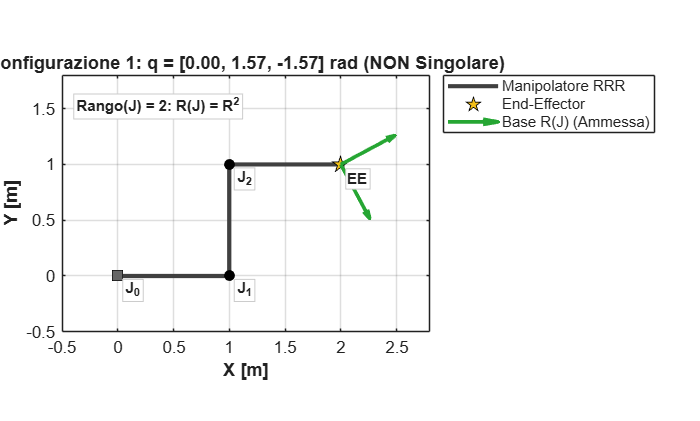


% --- Visualizzazione Grafica Configurazione 1 ---
col_link  = [0.25, 0.25, 0.25];
col_green = [0.15, 0.65, 0.20];
col_red   = [0.85, 0.15, 0.15];

figure('Name', 'Analisi Mobilita Configurazione 1', 'Color', 'w');
hold on; grid on; box on; axis equal;
xlabel('X [m]', 'FontWeight', 'bold');
ylabel('Y [m]', 'FontWeight', 'bold');

% Calcolo Posizioni Snodi
p0 = [0, 0];
p1 = p0 + [l_vals(1)*cos(q_vals(1)), l_vals(1)*sin(q_vals(1))];
p2 = p1 + [l_vals(2)*cos(q_vals(1)+q_vals(2)), l_vals(2)*sin(q_vals(1)+q_vals(2))];
p3 = p2 + [l_vals(3)*cos(sum(q_vals)), l_vals(3)*sin(sum(q_vals))];
pts_arm = [p0; p1; p2; p3];

% Bracci e Marker Gerarchici
h_arm = plot(pts_arm(:,1), pts_arm(:,2), '-', 'Color', col_link, 'LineWidth', 2.5, ...
    'DisplayName', 'Manipolatore RRR');
plot(pts_arm(2:3,1), pts_arm(2:3,2), 'o', 'MarkerSize', 6, ...
    'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');
plot(p0(1), p0(2), 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', [0.4, 0.4, 0.4], 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');
h_ee = plot(p3(1), p3(2), 'p', 'MarkerSize', 10, ...
    'MarkerFaceColor', [0.95, 0.75, 0.10], 'MarkerEdgeColor', 'k', 'DisplayName', 'End-Effector');

% Direzioni di Mobilita R(J) (Verdi)
scale_v = 0.55;
h_rj = quiver(p3(1), p3(2), R_J1(1,1)*scale_v, R_J1(2,1)*scale_v, 0, ...
    'Color', col_green, 'LineWidth', 2.2, 'MaxHeadSize', 0.5, 'DisplayName', 'Base R(J) (Ammessa)');
if size(R_J1, 2) > 1
    quiver(p3(1), p3(2), R_J1(1,2)*scale_v, R_J1(2,2)*scale_v, 0, ...
        'Color', col_green, 'LineWidth', 2.2, 'MaxHeadSize', 0.5, 'HandleVisibility', 'off');
end

% Etichette Giunti con Raggruppamento Automatico Coincidenze
lbls = {'J_0', 'J_1', 'J_2', 'EE'};
visited = false(4, 1);
for idx = 1:4
    if visited(idx), continue; end
    dists = sqrt(sum((pts_arm - pts_arm(idx,:)).^2, 2));
    coinc = find(dists < 1e-4);
    visited(coinc) = true;
    txt_lbl = strjoin(lbls(coinc), ', ');
    text(pts_arm(idx,1) + 0.06, pts_arm(idx,2) - 0.13, txt_lbl, ...
        'FontSize', 9, 'FontWeight', 'bold', ...
        'BackgroundColor', [1 1 1], 'EdgeColor', [0.8 0.8 0.8], 'Margin', 1);
end

text(-0.38, 1.52, 'Rango(J) = 2: R(J) = R^2', ...
    'FontSize', 9, 'FontWeight', 'bold', ...
    'BackgroundColor', [1 1 1], 'EdgeColor', [0.8 0.8 0.8], 'Margin', 1);

title(sprintf('Configurazione 1: q = [%.2f, %.2f, %.2f] rad (NON Singolare)', q_vals), ...
    'FontSize', 11, 'FontWeight', 'bold');
legend([h_arm, h_ee, h_rj], 'Location', 'bestoutside');
xlim([-0.5, 2.8]); ylim([-0.5, 1.8]);
hold off;

### Giustificazione Risultati Punto Di Vista Meccanico

In questa configurazione:

- Il primo braccio $l_1$ giace lungo l'asse X, poiché $q_1=0$.

- Il secondo braccio $l_2$ è ruotato di $q_2 = \frac{\pi}{2}$ rispetto al primo, puntando quindi lungo l'asse Y.

- Il terzo braccio $l_3$ è ruotato di $q_3 = -\frac{\pi}{2}$ rispetto al secondo, risultando quindi parallelo all'asse X e orientato nella stessa direzione del primo braccio.

- La posizione dell'end-effector è la somma vettoriale dei bracci: $p_E = (l_1 + l_3, l_2) = (1+1, 1) = (2,1)$.

**Analisi di Mobilità *****(Configurazione NON Singolare)***

Il calcolo mostra che il **rango** dello **Jacobiano** è **2**, ovvero il massimo possibile (rango pieno), dato che lo spazio di lavoro è bidimensionale ($m=2$).

Poiché $\rho(J_L)=m$, lo Spazio delle Velocità Raggiungibili $R(J_L)$ coincide con l'intero piano $\mathbb{R}^2$. Di conseguenza, il suo complemento ortogonale, lo spazio delle Direzioni di Moto Precluse $N(J_L^T)$, è banale (contiene solo il vettore nullo).

La configurazione non è singolare perché i movimenti generati dai singoli giunti sono linearmente indipendenti. Una rotazione del giunto 1 ($\dot{q}_1$) farebbe ruotare l'intera struttura attorno all'origine, producendo una velocità dell'end-effector istantaneamente tangente a un cerchio (in questo caso, lungo la direzione $[-1,1]$). Le rotazioni dei giunti 2 e 3 ($\dot{q}_2, \dot{q}_3$) producono movimenti che non sono paralleli a quello generato dal giunto 1. Poiché è possibile generare velocità in direzioni non collineari, la loro combinazione lineare può produrre un vettore di velocità arbitrario nel piano $(v_x, v_y)$. L'end-effector può quindi muoversi istantaneamente in qualsiasi direzione.

**Analisi degli Automovimenti *****(Ridondanza)***

Il manipolatore è ridondante per il posizionamento 2D ($n=3>m=2$). La dimensione dello spazio nullo (automovimenti) è data da $n - \rho(J_L) = 3 - 2 = 1$.

Esiste una base per $N(J_L)$ con un solo vettore, come calcolato. Questo vettore definisce una combinazione specifica di velocità dei giunti $\dot{q} \in N(J_L)$ che risulta in una velocità nulla dell'end-effector $v = J_L \dot{q} = 0$.

La presenza di un automovimento significa che il robot può **riconfigurare la sua postura interna mantenendo l'end-effector fermo**. Si può immaginare un movimento coordinato del giunto 2 e del giunto 3, compensato dal giunto di base (giunto 1), che permette alla struttura di muoversi pur mantenendo la punta fissa in $(2,1)$. Questa capacità aggiuntiva è un vantaggio della ridondanza, utilizzata ad esempio per evitare ostacoli con il corpo del robot senza spostare l'end-effector.

## Configurazione 2: Robot Completamente Ripiegato su se stesso

I parametri del robot sono


$$l_1 =l_2 =l_3 =1$$



$$q_1 =0~~~~q_2 =\pi ~~~~q_3 =0$$


% Valori numerici per la configurazione
q1_val_2 = 0;
q2_val_2 = pi;
q3_val_2 = 0;
q_vals_2 = [q1_val_2, q2_val_2, q3_val_2];

fprintf('------------ Configurazione q = [%.2f, %.2f, %.2f] ------------', q_vals_2(1), q_vals_2(2), q_vals_2(3));

------------ Configurazione q = [0.00, 3.14, 0.00] ------------


% Sostituzione dei valori numerici nello Jacobiano lineare simbolico
vars_sym = [l1, l2, l3, q1, q2, q3];
vals_num = [l_vals, q_vals_2];
J1_num = double(subs(J_L, vars_sym, vals_num));

fprintf('Jacobiano Lineare Numerico:\n');

Jacobiano Lineare Numerico:


disp(J1_num);

     0     0     0
    -1    -2    -1



% Verifica Singolarità
rank_J1 = rank(J1_num);
fprintf('Rango dello Jacobiano: %d\n', rank_J1);

Rango dello Jacobiano: 1


% Dimensione Spazio Lavoro
m = size(J_L, 1);
% Numero Di Giunti
n = size(DH_Table, 1);

if rank_J1 < m
    fprintf('Configurazione Singolare (Rango < m)');

    % Spazio Velocità Raggiungibili (Immagine di J)
    R_J1 = orth(J1_num);
    fprintf('Base Spazio Velocità Raggiungibili R(J):\n');
    disp(R_J1);
    % L'End-Effector Può Muoversi Solo Lungo La Direzione Di Questo Vettore

    % Direzioni Di Moto Precluse (Nucleo di J^T)
    N_J1_T = null(J1_num.');
    fprintf('Base Direzioni Di Moto Precluse N(J^T):\n');
    disp(N_J1_T);
    % L'End-Effector È Bloccato E Non Può Muoversi Lungo Direzione Di Questo Vettore
else
    fprintf('Configurazione NON Singolare (Rango Pieno)');

    % Spazio Velocità Raggiungibili (Immagine di J)
    R_J1 = orth(J1_num);
    fprintf('Base Spazio Velocità Raggiungibili R(J):\n');
    disp(R_J1);
    % L'End-Effector Può Muoversi Solo Lungo La Direzione Di Questo Vettore

    % Direzioni Di Moto Precluse (Nucleo di J^T)
    fprintf('Non Ci Sono Direzioni Di Moto Precluse N(J^T)!');
end

Configurazione Singolare (Rango < m)

Base Spazio Velocità Raggiungibili R(J):


     0
     1



Base Direzioni Di Moto Precluse N(J^T):


    -1
     0



% Per Robot Ridondanti
if n > m
    % Automovimenti (Nucleo di J)
    A_J1 = null(J1_num);
    fprintf('Base Automovimenti N(J):\n');
    disp(A_J1);
    % Sono Possibili Due Moti Senza Spostare La Punta Del Robot
    dim_A = size(A_J1, 2);
    fprintf('Numero Automovimenti: %d\n', dim_A);
else
    fprintf('Robot Non Ridondante (n <= m), Non Esistono Automovimenti\n');
end

Base Automovimenti N(J):


   -0.9129         0
    0.3651   -0.4472
    0.1826    0.8944



Numero Automovimenti: 2


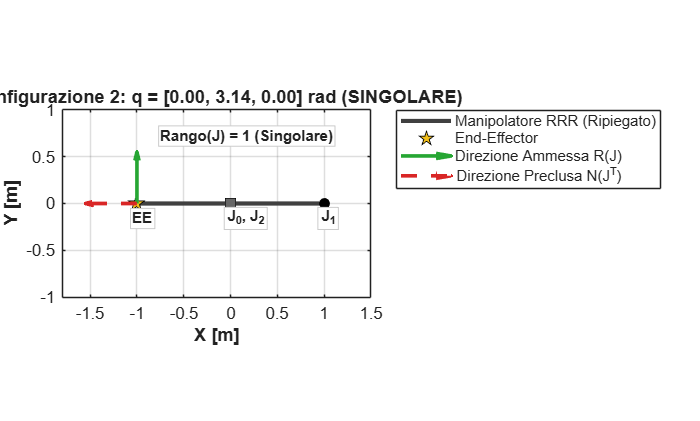


% --- Visualizzazione Grafica Configurazione 2 ---
figure('Name', 'Analisi Mobilita Configurazione 2', 'Color', 'w');
hold on; grid on; box on; axis equal;
xlabel('X [m]', 'FontWeight', 'bold');
ylabel('Y [m]', 'FontWeight', 'bold');

% Calcolo Posizioni Snodi
p0 = [0, 0];
p1 = p0 + [l_vals(1)*cos(q_vals_2(1)), l_vals(1)*sin(q_vals_2(1))];
p2 = p1 + [l_vals(2)*cos(q_vals_2(1)+q_vals_2(2)), l_vals(2)*sin(q_vals_2(1)+q_vals_2(2))];
p3 = p2 + [l_vals(3)*cos(sum(q_vals_2)), l_vals(3)*sin(sum(q_vals_2))];
pts_arm = [p0; p1; p2; p3];

% Bracci e Marker Gerarchici
h_arm = plot(pts_arm(:,1), pts_arm(:,2), '-', 'Color', col_link, 'LineWidth', 2.5, ...
    'DisplayName', 'Manipolatore RRR (Ripiegato)');
plot(pts_arm(2:3,1), pts_arm(2:3,2), 'o', 'MarkerSize', 6, ...
    'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');
plot(p0(1), p0(2), 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', [0.4, 0.4, 0.4], 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');
h_ee = plot(p3(1), p3(2), 'p', 'MarkerSize', 10, ...
    'MarkerFaceColor', [0.95, 0.75, 0.10], 'MarkerEdgeColor', 'k', 'DisplayName', 'End-Effector');

% Direzione Ammessa R(J) (Verde) e Preclusa N(J^T) (Rossa Tratteggiata)
scale_v = 0.55;
h_rj = quiver(p3(1), p3(2), R_J1(1)*scale_v, R_J1(2)*scale_v, 0, ...
    'Color', col_green, 'LineWidth', 2.2, 'MaxHeadSize', 0.5, 'DisplayName', 'Direzione Ammessa R(J)');
h_njt = quiver(p3(1), p3(2), N_J1_T(1)*scale_v, N_J1_T(2)*scale_v, 0, ...
    'Color', col_red, 'LineStyle', '--', 'LineWidth', 2.2, 'MaxHeadSize', 0.5, 'DisplayName', 'Direzione Preclusa N(J^T)');

% Etichette Giunti con Raggruppamento Automatico Coincidenze (J_0, J_2 in origine)
lbls = {'J_0', 'J_1', 'J_2', 'EE'};
visited = false(4, 1);
for idx = 1:4
    if visited(idx), continue; end
    dists = sqrt(sum((pts_arm - pts_arm(idx,:)).^2, 2));
    coinc = find(dists < 1e-4);
    visited(coinc) = true;
    txt_lbl = strjoin(lbls(coinc), ', ');
    text(pts_arm(idx,1) - 0.05, pts_arm(idx,2) - 0.16, txt_lbl, ...
        'FontSize', 9, 'FontWeight', 'bold', ...
        'BackgroundColor', [1 1 1], 'EdgeColor', [0.8 0.8 0.8], 'Margin', 1);
end

text(-0.75, 0.72, 'Rango(J) = 1 (Singolare)', ...
    'FontSize', 9, 'FontWeight', 'bold', ...
    'BackgroundColor', [1 1 1], 'EdgeColor', [0.8 0.8 0.8], 'Margin', 1);

title(sprintf('Configurazione 2: q = [%.2f, %.2f, %.2f] rad (SINGOLARE)', q_vals_2), ...
    'FontSize', 11, 'FontWeight', 'bold');
legend([h_arm, h_ee, h_rj, h_njt], 'Location', 'bestoutside');
xlim([-1.8, 1.5]); ylim([-1.0, 1.0]);
hold off;

### Giustificazione Risultati Punto Di Vista Meccanico

In questa configurazione, il robot è ripiegato su se stesso:

- Il primo braccio $l_1$ è orientato lungo l'asse X ($q_1 = 0$).

- Il secondo braccio $l_2$ è ruotato di $q_2 = \pi$, ripiegandosi completamente all'indietro e allineandosi con l'asse X in direzione negativa.

- Il terzo braccio $l_3$ è ruotato di $q_3 = 0$ rispetto al secondo, quindi prosegue nella stessa direzione del secondo braccio.

- La posizione dell'end-effector è $p_E = (-1,0)$.

**Analisi di Mobilità *****(Configurazione Singolare)***

Il calcolo mostra che il **rango** dello **Jacobiano** è **1**. Poiché $\rho(J_L)<m$, la configurazione è **singolare**.

Lo Spazio delle Velocità Raggiungibili $R(J_L)$ ha dimensione 1. La sua base, data dal vettore $[0,1]^T$, indica che l'unica direzione di moto possibile è lungo l'asse Y. Le Direzioni di Moto Precluse $N(J_L^T)$ hanno dimensione $m - \rho(J_L) = 2-1 = 1$. La sua base, data dal vettore $[-1,0]^T$, indica che il moto lungo l'asse X è impossibile.

La singolarità emerge perché tutti i bracci sono allineati. Qualsiasi piccola rotazione di uno qualsiasi dei tre giunti provoca un movimento della punta del robot, che in questa postura è sempre perpendicolare alla linea dei bracci (cioè, lungo l'asse Y). È fisicamente impossibile generare una velocità istantanea dell'end-effector lungo la direzione dei bracci stessi (l'asse X). Un tentativo di spingere o tirare l'end-effector lungo l'asse X si tradurrebbe solo in forze di compressione/trazione interne alla struttura, senza produrre alcun movimento.

**Analisi degli Automovimenti *****(Effetto Singolarità)***

In una configurazione singolare, la dimensione dello spazio degli automovimenti aumenta, cioè $n - \rho(J_L) = 3-1 = 2$.

Esistono due combinazioni linearmente indipendenti di velocità dei giunti che mantengono l'end-effector fermo. La base di $N(J_L)$ calcolata contiene i due vettori che definiscono questi movimenti. La perdita di un grado di libertà nel movimento dell'end-effector (non può muoversi lungo l'asse X) si traduce in un **guadagno di un grado di libertà nel movimento** del robot. Oltre all'automovimento già presente dovuto alla ridondanza, la singolarità ne introduce un secondo. Intuitivamente, i giunti possono muoversi in modi più complessi e coordinati (descritti dai due vettori) per riarrangiare la postura del robot lungo l'asse X senza che la punta, bloccata a $x=-1$, si sposti.